# Determine Allan Variance of Single Axis Gyroscope

Load gyroscope data from a MAT file, including the sample rate of the data in Hz. Calculate the Allan variance.

load('LoggedSingleAxisGyroscope','omega','Fs')
[avar,tau] = allanvar(omega,'octave',Fs);

Plot the Allan variance on a `loglog` plot.

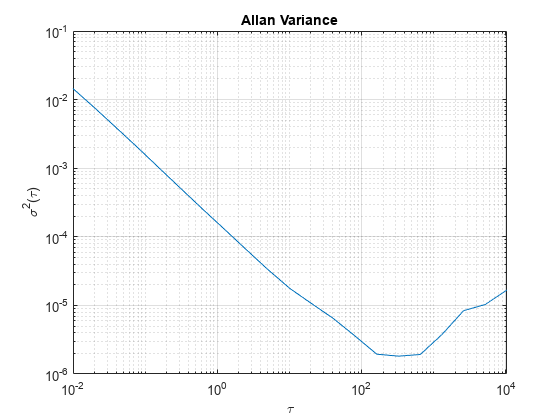

loglog(tau,avar)
xlabel('\tau')
ylabel('\sigma^2(\tau)')
title('Allan Variance')
grid on

*Copyright 2018 The MathWorks, Inc.*